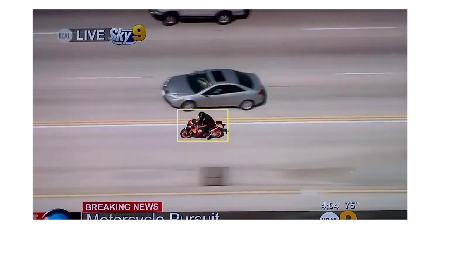

% myTracker,  codi inicial del short project

close all

% Llegim el fitxer d'anotacions groundtruth_rect.txt: frame, bounding boxes, is_lost
BB = importdata('./shortProject/MotorcycleChase/MotorcycleChase/groundtruth_rect.txt');
Idir = dir('./shortProject/MotorcycleChase/MotorcycleChase/img/*.jpg');

figure
hold on % mantenim sempre oberta la mateixa figura

% filtre de Kalman
initialStateP = [BB(1,2) 0 BB(1,3) 0]; % posicio inicial i velocitat
initialStateW = [BB(1,4) 0 BB(1,5) 0]; % mida inicial i velocitat
KFP = trackingKF('MotionModel','2D Constant Velocity','State',initialStateP);
KFW = trackingKF('MotionModel','2D Constant Velocity','State',initialStateW);

nf = size(Idir); % nombre total de fitxers imatges
for i = 1:nf
    filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    I = imread(filename);
    
    predP = predict(KFP); % predictor de la posicio de la finestra per Kalman
   
    correct(KFP,BB(i,2:3)); % indiquem la nova posicio detectada
    
    predW = predict(KFW); % predictor de l'amplada/alcada de la finestra per Kalman
    % predW = BB(i,4:5);
    % correct(KFW,BB(i,4:5)); comentar això
    correct(KFW,BB(i,4:5));

    %calculem el –overlap, intersection over union-- de les finestres 
    overlapRatio = bboxOverlapRatio([predP(1),predP(3),predW(1),predW(3)],BB(i,2:5));

    % mostrem els resultats sobre la imatge
    imshow(I) % mostra el frame 
    % mostrem els rectangles:  correcte (en groc) i el predit (en vermell)
    rectangle('Position',[predP(1),predP(3),predW(1),predW(3)],'EdgeColor','red');
    rectangle('Position',BB(i,2:5),'EdgeColor','yellow');
    drawnow
end

% amplada i alçada KFW (ignorem), utilitzem el BB(i,4:5)


% reconeixement, prenc caracteristiques de la moto en el video ( i del que
% no es moto). Aprenc el que es una moto i tindrem una funcio de
% classificacio. Quan executem un altre cop el video detectarem la moto per
% reconeixement.
% tracking, amplada i alçada del groundtrouh, les altres mirem de
% detectarles un 40% mes lluny que l'anterior (si medeix 100 mirem 20 a
% esquerra i dreta)

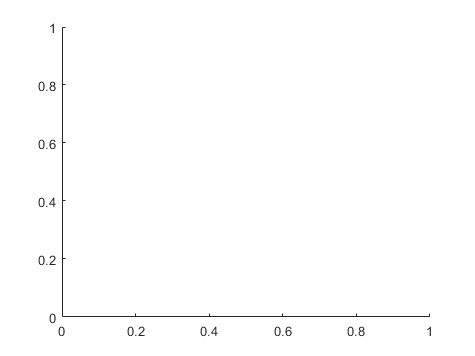

close all
hold off

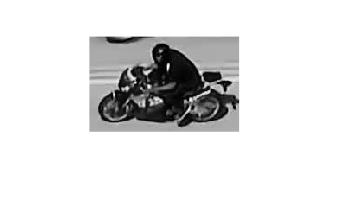


BB = importdata('./shortProject/MotorcycleChase/MotorcycleChase/groundtruth_rect.txt');
Idir = dir('./shortProject/MotorcycleChase/MotorcycleChase/img/*.jpg');

figure
hold on % mantenim sempre oberta la mateixa figura


%while hasFrame(VideoReader)
filename = horzcat(Idir(1).folder,'/',Idir(1).name);
I = imread(filename);
B1 = BB(1,2:5);
im_obj = rgb2gray(imcrop(I,B1));
imshow(im_obj)


nf = size(Idir); % nombre total de fitxers imatges
for i = 1:nf
   filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    I2 = imread(filename);
    im_esc = rgb2gray(I2);
    % SIFT
    kp_obj = detectSIFTFeatures(im_obj);
    kp_esc = detectSIFTFeatures(im_esc);

    [feat_obj, kp_obj] = extractFeatures(im_obj,kp_obj);
    [feat_esc, kp_esc] = extractFeatures(im_esc,kp_esc);

    pairs = matchFeatures(feat_obj, feat_esc, 'MatchThreshold',2);

    m_kp_obj = kp_obj(pairs(:,1)); % agafem els millors punts
    m_kp_esc = kp_esc(pairs(:,2));

    % Ransac
    [T] = estimateGeometricTransform2D(m_kp_obj,m_kp_esc, "affine");

    [fo,co] = size(im_obj);
    [fe,ce] = size(im_esc);

    box = [1,1; co,1; co,fo; 1,fo; 1,1];

    nbox = transformPointsForward(T,box);
    imshow(I2)
    hold on
    line(nbox(:,1),nbox(:,2));
    drawnow
end